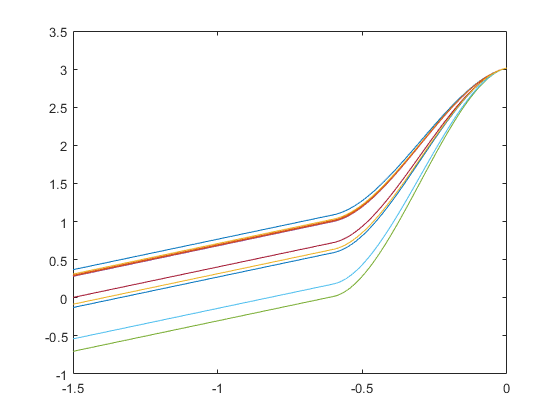

% HISTORY FUNCTION TEST
N = 10;
g = 1.5;
w0 = 1.0;
tau0_0 = 0.6;
tau0 = tau0_0*ones(N); % exprnd(4, N);
A = ones(N);

Omega0 = 0.8*ones(1,N);
phases0 = (pi/2)*rand(1,N); % linspace(0,pi/2,N);

parameters = struct('g', g, 'omega0', w0, 'tau0', tau0, 't0', 0, 'A', A, ...
    'phirange', [0,pi], 'numphis', 100);

linear_fun = @(t) Omega0*(t - tau0_0) + phases0;

hist_fun = IVPhistory(Omega0, phases0, parameters);
phi_fun = hist_fun.y;
phip_fun = hist_fun.yp;

t_arr = linspace(-1.5, 0, 1000);
y_arr = NaN(N, numel(t_arr));
yp_arr = NaN(N, numel(t_arr));
for i = 1:numel(t_arr)
    y_arr(:,i) = phi_fun(t_arr(i));
    yp_arr(:,i) = phip_fun(t_arr(i));
end

figure;
plot(t_arr, y_arr);

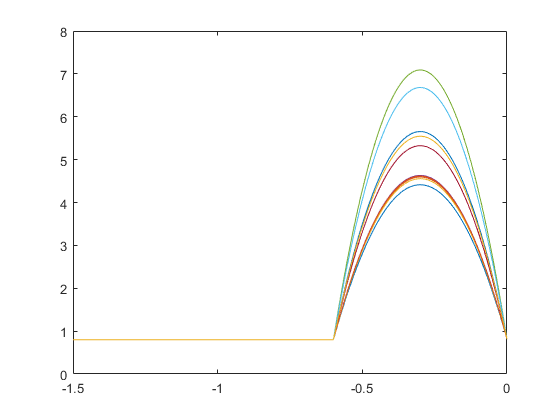


figure;
plot(t_arr, yp_arr);